# Calculate Basic Statistics

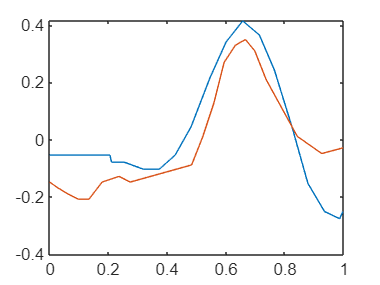

%Instructions are in the task pane to the left. Complete and submit each task one at a time.
% Do not edit. This code loads and plots the data.
load sampleletters.mat
plot(b1.Time,b1.X)
hold on
plot(b2.Time,b2.X)
hold off

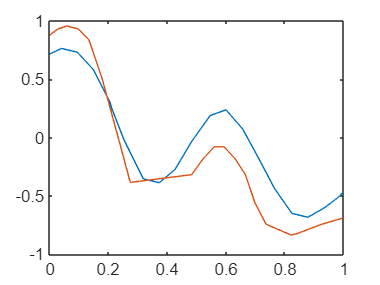

plot(b1.Time,b1.Y)
hold on
plot(b2.Time,b2.Y)
hold off

## Task 1

The MAT-file `sampleletters.mat` contains tables `b1`, `b2`, `d1`, `d2`, `m1`, `m2`, `v1`, and `v2` that hold the data for some specific examples selected from the full handwriting data set.

**TASK**

Use the `range` function to calculate the aspect ratio of the letter `b1` by dividing the range of values of `Y` by the range of values of `X`. Assign the result to a variable called `aratiob`.

**Hint**

Divide `range``(``b1.Y``)` by `range``(``b1.X``)`.

aratiob = range(b1.Y)/range(b1.X)

aratiob = 2.0952

## Task 2

The letters are preprocessed to have a mean of 0 (in both `X` and `Y`). The median is less sensitive to outliers than the mean. Comparing the mean to the median can give an idea of how asymmetric a distribution is.

**TASK**

Use the `median` function to calculate the median of `b1.X` and `b1.Y`. Store the results in variables called `medxb` and `medyb`, respectively. Remember to use the `"omitnan"` flag.

**Hint**

Calculate `median``(``b1.X``,``"omitnan"``)` and similarly for `b1.Y`.

medxb = median(b1.X,"omitnan")

medxb = -0.0538

medyb = median(b1.Y,"omitnan")

medyb = -0.0336

## Task 3

The spread of values can be measured with the mean absolute deviation (MAD), standard deviation, and variance. Each of these calculate the average of some measure of the deviation from the mean.

**TASK**

Use the `mad` function to calculate the mean absolute deviation of `b1.X` and `b1.Y`. Store the results in variables called `devxb` and `devyb`, respectively. Note that `mad` ignores NaNs by default.

**Hint**

Calculate `mad``(``b1.X``)` and similarly for `b1.Y`.

devxb = mad(b1.X)

devxb = 0.1519

devyb = mad(b1.Y)

devyb = 0.4195

## Task 4

**TASK**

Calculate the same statistics for some other sample letters:

- The aspect ratio of `v1`, stored in `aratiov`

- The median of `d1.X`, stored in `medxd`

- The median of `d1.Y`, stored in `medyd`

- The mean absolute deviation of `m1.X`, stored in `devxm`

- The mean absolute deviation of `m1.Y`, stored in `devym`

**Hint**

Copy and paste the commands from the previous tasks and change the input and output variable names.

aratiov = range(v1.Y)/range(v1.X)

aratiov = 1.5942

medxd = median(d1.X,"omitnan")

medxd = 0.0431

medyd = median(d1.Y,"omitnan")

medyd = 0.0184

devxm = mad(m1.X)

devxm = 0.2865

devym = mad(m1.Y)

devym = 0.2560

## Further Practice

How do the values compare for different letters? Will these statistics be useful features? Try calculating the same statistics for a second sample of the same letters (`b2`, `d2`, `m2`, and `v2`).

This plot shows the aspect ratio and MAD of the horizontal position of the eight letter samples:

As you might expect, the letter b is tall, while m is wide. The letters m and v are more spread horizontally than b and d.

You might want to visualize the samples to see why d has a lower aspect ratio than b:

`plot``(``b1.X``,``b1.Y``,``b2.X``,``b2.Y``)`

`axis``([``-1` `1` `-1` `1``])`

`axis` `equal`

`plot``(``d1.X``,``d1.Y``,``d2.X``,``d2.Y``)`

`axis``([``-1` `1` `-1` `1``])`

`axis` `equal`

What else can distinguish between b and d? Look at the values of the median horizontal position.

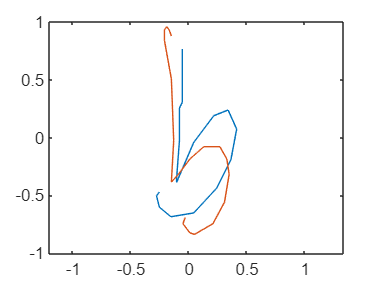

plot(b1.X,b1.Y,b2.X,b2.Y)
axis([-1 1 -1 1])
axis equal

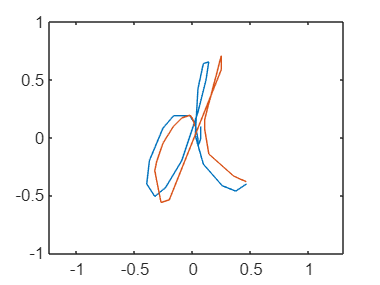

plot(d1.X,d1.Y,d2.X,d2.Y)
axis([-1 1 -1 1])
axis equal

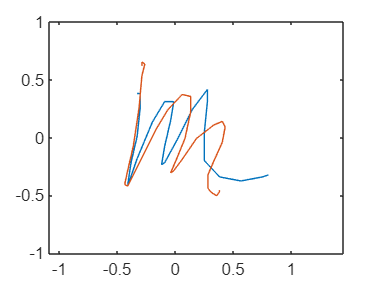


plot(m1.X,m1.Y,m2.X,m2.Y)
axis([-1 1 -1 1])
axis equal

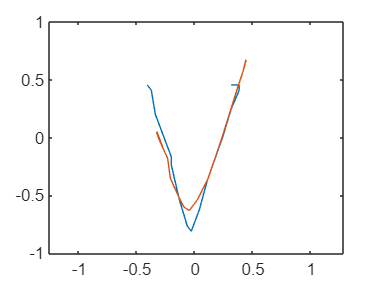

plot(v1.X,v1.Y,v2.X,v2.Y)
axis([-1 1 -1 1])
axis equal